# L9 Group Assignment

## Samples of a Population - Test Data

Before software is tested on real data, it is tested with well-controlled test data. Test data is 

generated after a discrete stochastic process that has the following signal model: 


$$X\left(n\right)=w\left(n\right)$$


where $w\left(n\right)$ is i.i.d and $w\left(n\right)=Ν\left(7,2\right)$

1. Are the samples Of X (n) statistically independent? 

Yes they are i.i.d.

2. Is the process ergodic? 

Yes it is.

3. Plot the data from one realisation of the process. 

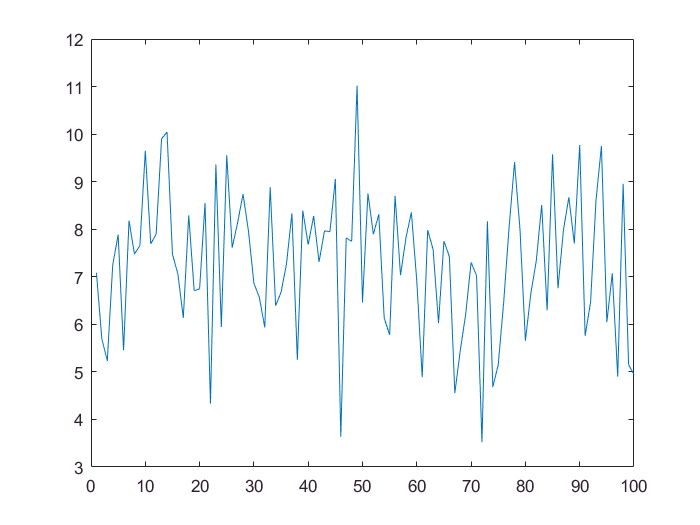

mu = 7; variance = 2;

X1 = sqrt(variance)*randn(1,100)+mu;
plot(X1)

4. What is the population in this case? 

The population is all realisations of the process X(n)

5. Use the formula to calculate the sample mean. 

X1_mean = 1/length(X1)*sum(X1)

X1_mean = 6.7970

6. Verify with the matlab function mean. 

X1_mean = mean(X1)

X1_mean = 6.7970

7. Use the formula to calculate the sample variance.

X1_var = 1/(length(X1)-1).*sum((X1-X1_mean).^2)

X1_var = 2.3125

8. Verify with the matlab function var. 

X1_var = var(X1)

X1_var = 2.3125

9. Find the z-score for the data. What does the z-score tell you?  

n = length(X1);
z = (X1_mean-mu)/(sqrt(variance)/sqrt(n))

z = -1.4355

10. Find the confidence interval for the mean (lower and upper endpoint). 

- Signifance level of $\alpha =0\ldotp 05$

- Confidence level of $1−\alpha =0\ldotp 95$

- Confidence interval is $\frac{\alpha }{2}$ because it is a two-sided test

Z value is found by inverse table look-up. 

lower_bound = X1_mean-norminv(0.975)*sqrt(2)/sqrt(length(X1))

lower_bound = 6.5198

upper_bound = X1_mean+norminv(0.975)*sqrt(2)/sqrt(length(X1))

upper_bound = 7.0742

11. Draw the confidence interval on the plot together with the data. What does the confidence interval tell you? 

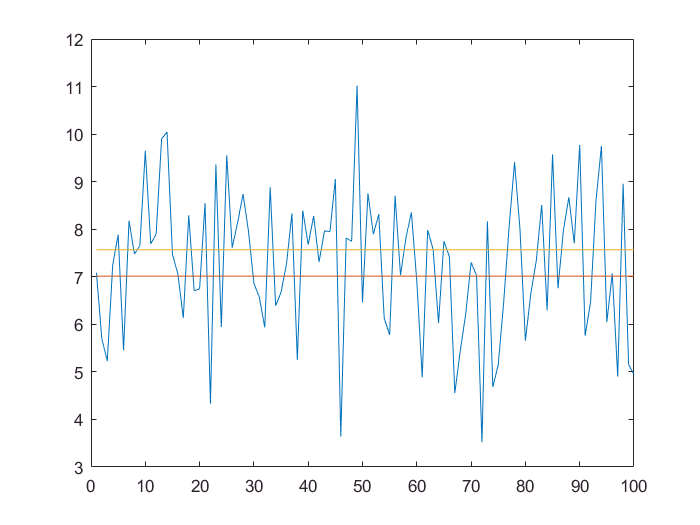

plot(X1)
hold on
plot(ones(1,length(X1)).*lower_bound)
hold on
plot(ones(1,length(X1)).*upper_bound)
hold off

12. How large a sample size do you actually need? 

- B is the desire uncertaincy

- n is the samplesize

B = norminv(0.975)*sqrt(2)/sqrt(length(X1))

B = 0.2772

n_min = (norminv(0.975)*sqrt(2)/B)^2

n_min = 100

13. Repeat questions 3 and 6, 30 times and make a histograms of the found sample means. What distribution do the samples have? 

- Normal distribution

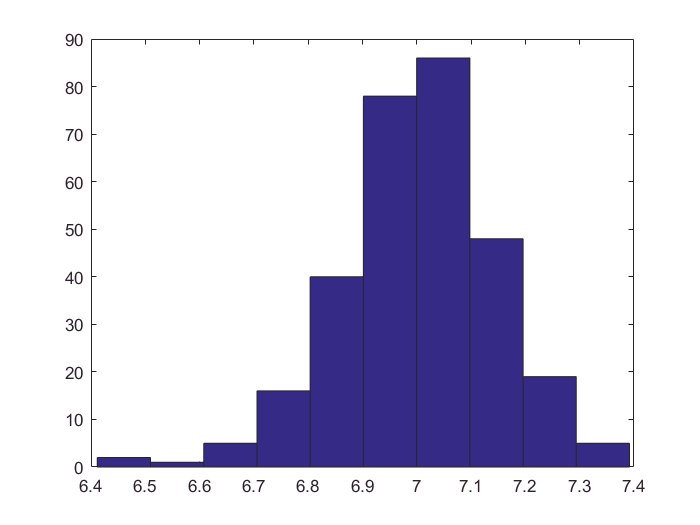

for i = 1:300
X1 = sqrt(variance)*randn(1,100)+mu;
meanX(i) = mean(X1);
end

figure(2)
hist(meanX)

14. What would happen in question 13, if the signal model was given as: $X\left(n\right)=w\left(n\right)$where $w\left(n\right)$ is i.i.d and $w\left(n\right)~U\left(5,9\right)$

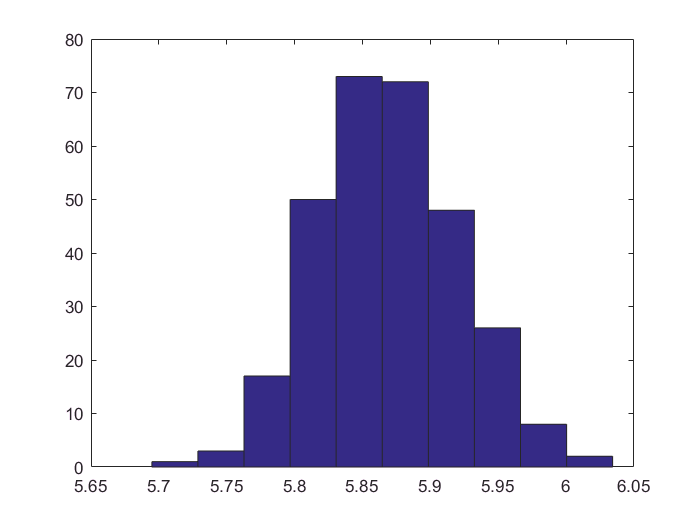

a = 5; b = 9;

for i = 1:300
X1 = sqrt(3)*rand(1,100)+a;
meanX(i) = mean(X1);
end

figure(3)
hist(meanX)